## Para el fichero 'Gala_8kHz.wav', con qmidriser() y qmidtread() de la tarea 1 con xsc=1. 

-     Obtened la SNR global, la SNR segmental y SNR por tramas. Representad junto a la señal original de forma análoga a “Ejemplo 2”. Utilizad n = 6 y L = 160. 

% n=6;
% L=160;
% [x, ~] = audioread('Gala_8kHz.wav');
% %Obtenemos las muestras del archivo a analizar.
% [y, ~,~, ~, ~] = qmidriser(x,1,n);
% 
% %Cuantificamos la señal original y obtenemos señal cuantificada en y.
% SNRq = SNR(x,y); % SNR de la señal cuantificada
% [SNRseg, SNRm, m] = SNRportramas(x,y,L);
% 
% num_muestras = 1:length(x);
% snr_vector = ones(size(num_muestras))*SNRq;
% SNRseg_vector = ones(size(num_muestras))*SNRseg;
% SNRm_interp = interp1(1:length(SNRm), SNRm, linspace(1, length(SNRm), length(num_muestras)));
% 
% % figure(1);
% % subplot(4,1,1),plot(num_muestras,snr_vector,'--',num_muestras,SNRseg_vector,'-.r',num_muestras,SNRm_interp,'-k');
% axis tight;
% xlabel('muestras');
% ylabel('SNR (dB)');
% title(' SNR (dB), midriser, n=6, xsc=1');
% legend('SNRq', 'SNRseg', 'SNRm');
% % subplot(2,1,2),plot(num_muestras,x);
% axis tight;

-     Explicad las variaciones de la SNR por tramas. ¿En qué tramos de la señal es mayor? ¿Es posible que en alguna trama sea cero?

% n=6;
% L=160;
% [x, ~] = audioread('Gala_8kHz.wav');
% %Obtenemos las muestras del archivo a analizar.
% [y, ~,~, ~, ~] = qmidtread(x,1,n);
% 
% %Cuantificamos la señal original y obtenemos señal cuantificada en y.
% SNRq = SNR(x,y); % SNR de la señal cuantificada
% [SNRseg, SNRm, m] = SNRportramas(x,y,L);
% 
% num_muestras = 1:length(x);
% snr_vector = ones(size(num_muestras))*SNRq;
% SNRseg_vector = ones(size(num_muestras))*SNRseg;
% SNRm_interp = interp1(1:length(SNRm), SNRm, linspace(1, length(SNRm), length(num_muestras)));
% 
% figure(2);
% subplot(4,1,1),plot(num_muestras,snr_vector,'--',num_muestras,SNRseg_vector,'-.r',num_muestras,SNRm_interp,'-k');
% axis tight;
% xlabel('muestras');
% ylabel('SNR (dB)');
% title(' SNR (dB), midtread, n=6, xsc=1');
% legend('SNRq', 'SNRseg', 'SNRm');
% % subplot(2,1,2),plot(num_muestras,x);
% axis tight;

## Repetid el apartado anterior para xsc=0.5 y xsc=0.3. Comparad y comentad los resultados.

% n=6;
% xsc=0.5;
% L=160;
% [x, ~] = audioread('Gala_8kHz.wav');
% [y, ~,~, ~, ~] = qmidriser(x,xsc,n);
% SNRq = SNR(x,y); % SNR de la señal cuantificada
% [SNRseg, SNRm, m] = SNRportramas(x,y,L);
% 
% num_muestras = 1:length(x);
% snr_vector = ones(size(num_muestras))*SNRq;
% SNRseg_vector = ones(size(num_muestras))*SNRseg;
% SNRm_interp = interp1(1:length(SNRm), SNRm, linspace(1, length(SNRm), length(num_muestras)));
% 
% % figure(2);
% % subplot(4,1,2),plot(num_muestras,snr_vector,'--',num_muestras,SNRseg_vector,'-.r',num_muestras,SNRm_interp,'-k');
% axis tight;
% xlabel('muestras');
% ylabel('SNR (dB)');
% title(' SNR (dB), midriser, n=6, xsc=0.5');
% legend('SNRq', 'SNRseg', 'SNRm');
% % subplot(2,1,2),plot(num_muestras,x); 
% axis tight;

% n=6;
% xsc=0.3;
% L=160;
% [y, ~,~, ~, ~] = qmidriser(x,xsc,n);
% SNRq = SNR(x,y); % SNR de la señal cuantificada
% [SNRseg, SNRm, m] = SNRportramas(x,y,L);
% 
% 
% num_muestras = 1:length(x);
% snr_vector = ones(size(num_muestras))*SNRq;
% SNRseg_vector = ones(size(num_muestras))*SNRseg;
% SNRm_interp = interp1(1:length(SNRm), SNRm, linspace(1, length(SNRm), length(num_muestras)));
% 
% % figure(2);
% % subplot(4,1,3),plot(num_muestras,snr_vector,'--',num_muestras,SNRseg_vector,'-.r',num_muestras,SNRm_interp,'-k');
% axis tight;
% xlabel('muestras');
% ylabel('SNR (dB)');
% title(' SNR (dB), midriser, n=6, xsc=0.3'); 
% legend('SNRq', 'SNRseg', 'SNRm');
% sgtitle('Gala con Qmidriser');
% % subplot(4,1,4),plot(num_muestras,x);
% axis tight;

% n=6;
% xsc=0.5;
% L=160;
% [y, ~,~, ~, ~] = qmidtread(x,xsc,n);
% SNRq = SNR(x,y); % SNR de la señal cuantificada
% [SNRseg, SNRm, m] = SNRportramas(x,y,L);
% 
% num_muestras = 1:length(x);
% snr_vector = ones(size(num_muestras))*SNRq;
% SNRseg_vector = ones(size(num_muestras))*SNRseg;
% SNRm_interp = interp1(1:length(SNRm), SNRm, linspace(1, length(SNRm), length(num_muestras)));
% 
% % figure(2);
% subplot(4,1,2),plot(num_muestras,snr_vector,'--',num_muestras,SNRseg_vector,'-.r',num_muestras,SNRm_interp,'-k');
% axis tight;
% xlabel('muestras');
% ylabel('SNR (dB)');
% title(' SNR (dB), midtread, n=6, xsc=0.5'); 
% legend('SNRq', 'SNRseg', 'SNRm');
% % subplot(2,1,2),plot(num_muestras,x); 
% axis tight;

% n=6;
% xsc=0.3;
% L=160;
% [y, ~,~, ~, ~] = qmidtread(x,xsc,n);
% SNRq = SNR(x,y); % SNR de la señal cuantificada
% [SNRseg, SNRm, m] = SNRportramas(x,y,L);
% 
% 
% num_muestras = 1:length(x);
% snr_vector = ones(size(num_muestras))*SNRq;
% SNRseg_vector = ones(size(num_muestras))*SNRseg;
% SNRm_interp = interp1(1:length(SNRm), SNRm, linspace(1, length(SNRm), length(num_muestras)));
% 
% % figure(2);
% subplot(4,1,3),plot(num_muestras,snr_vector,'--',num_muestras,SNRseg_vector,'-.r',num_muestras,SNRm_interp,'-k');
% axis tight;
% xlabel('muestras');
% ylabel('SNR (dB)');
% title(' SNR (dB), midtread, n=6, xsc=0.3');
% legend('SNRq', 'SNRseg', 'SNRm');
% sgtitle('Gala con Qmidtread ');
% subplot(4,1,4),plot(num_muestras,x);
% axis tight;

## Para los ficheros Gala_8kHz.wav e Afonso_8kHz.wav, con n=1:8, xsc=1. 

- Obtened la SNR global en todos los casos, considerando qmidriser() y qmidtread(). 

- Representad resultados como en la gráfica de la diapositiva “Ejemplo 3”. 

n=1:8;
xsc=1;
[x, fs] = audioread('Gala_8khz.wav');
SNRq_valores_tread_1 = zeros(size(n));

for i=1:length(n)

    [y, ~,~, ~, ~] = qmidtread(x,xsc,i);  % Cuantificacion midriser al fichero Gala
    SNRr = SNR(x,y); % SNR de la señal cuantificada    
    SNRq_valores_tread_1(i) = SNRr;
    
end

n=1:8;
xsc=1;
[x, fs] = audioread('Afonso_8khz.wav');
SNRq_valores_tread_1_af = zeros(size(n));

for i=1:length(n)

    [y, ~,~, ~, ~] = qmidtread(x,xsc,i);  % Cuantificacion midriser al fichero Afonso
    SNRr = SNR(x,y); % SNR de la señal cuantificada    
    SNRq_valores_tread_1_af(i) = SNRr;
    
end

% SNRq_valores_tread = zeros(size(n));
% 
% for i=1:length(n)
% 
%     [y, ~,~, ~, ~] = qmidtread(x,xsc,i);  % Cuantificacion midriser al fichero Gala
%     SNRt = SNR(x,y); % SNR de la señal cuantificada    
%     SNRq_valores_tread(i) = SNRt;
%     
% end

    Rb=fs*n;
    SNR1 = 6.02*n;
    SNR2 = 6.02*n - 7.27;
               
% plot(Rb,SNR1,'k',Rb,SNR2,'r',Rb,SNRq_valores_riser,'g',Rb,SNRq_valores_tread,'m'); ax = gca; ax.XTick = Rb; grid 

% Nombre a los ejes y titulo
% xlabel('Rb (kbps)'),ylabel('SNR (dB)'),title('SNR global, xsc=1,n=1:8');
% 
% % Leyenda 
% legend('SNR1','SNR2','Gala midriser','Gala midtread','fontsize',8,'FontWeight','bold');


- Repetid para n=1:8, xsc=0.5 y xsc=0.3. En este apartado sólo con qmidriser(). 

n=1:8;
xsc =0.5;
[x, fs] = audioread('Gala_8khz.wav');
SNRq_valores_tread_0_5 = zeros(size(n));

for i=1:length(n)

    [y, ~,~, ~, ~] = qmidtread(x,xsc,i);  % Cuantificacion midriser al fichero Gala
    SNRr = SNR(x,y); % SNR de la señal cuantificada    
    SNRq_valores_tread_0_5(i) = SNRr;
    
end

n=1:8;
xsc =0.5;
[x, fs] = audioread('Afonso_8khz.wav');
SNRq_valores_tread_0_5_af = zeros(size(n));

for i=1:length(n)

    [y, ~,~, ~, ~] = qmidriser(x,xsc,i);  % Cuantificacion midriser al fichero Afonso
    SNRr = SNR(x,y); % SNR de la señal cuantificada    
    SNRq_valores_tread_0_5_af(i) = SNRr;
    
end


 Rb=fs*n;
    SNR1 = 6.02*n;
    SNR2 = 6.02*n - 7.27;
               
% plot(Rb,SNR1,'k',Rb,SNR2,'r',Rb,SNRq_valores_riser,'g'); ax = gca; ax.XTick = Rb; grid 
% 
% % Nombre a los ejes y titulo
% xlabel('Rb (kbps)'),ylabel('SNR (dB)'),title('SNR global, midriser, xsc=0.5,n=1:8');
% 
% % Leyenda 
% legend('SNR1','SNR2','Gala midriser','fontsize',8,'FontWeight','bold');

% Observamos que al disminuir el valor de sobrecarga del cuantificador
% doblamos la potencia de la señal (+6 dB), pasando por ejemplo, en Rb=8kbps de -12dB de SNR 
% con xsc =1 a una SNR de -6 dB con xsc=0.5


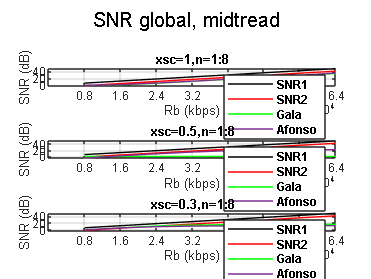

n=1:8;
xsc =0.3;
[x, fs] = audioread('Gala_8khz.wav');
SNRq_valores_tread_0_5 = zeros(size(n));

for i=1:length(n)

    [y, ~,~, ~, ~] = qmidtread(x,xsc,i);  % Cuantificacion midriser al fichero Gala
    SNRr = SNR(x,y); % SNR de la señal cuantificada    
    SNRq_valores_tread_0_3(i) = SNRr;
    
end


n=1:8;
xsc =0.3;
[x, fs] = audioread('Afonso_8khz.wav');
SNRq_valores_tread_0_3_af = zeros(size(n));

for i=1:length(n)

    [y, ~,~, ~, ~] = qmidtread(x,xsc,i);  % Cuantificacion midriser al fichero Afonso
    SNRr = SNR(x,y); % SNR de la señal cuantificada    
    SNRq_valores_tread_0_3_af(i) = SNRr;
    
end

 Rb=fs*n;
    SNR1 = 6.02*n;
    SNR2 = 6.02*n - 7.27;
               
% plot(Rb,SNR1,'k',Rb,SNR2,'r',Rb,SNRq_valores_riser,'g'); ax = gca; ax.XTick = Rb; grid 

figure(5)
subplot(3,1,1),plot(Rb,SNR1,'k',Rb,SNR2,'r',Rb,SNRq_valores_tread_1,'g',Rb,SNRq_valores_tread_1_af); ax = gca; ax.XTick = Rb; grid
% Nombre a los ejes y titulo
xlabel('Rb (kbps)'),ylabel('SNR (dB)'),title('xsc=1,n=1:8');
legend('SNR1','SNR2','Gala','Afonso','fontsize',8,'FontWeight','bold');
subplot(3,1,2),plot(Rb,SNR1,'k',Rb,SNR2,'r',Rb,SNRq_valores_tread_0_5,'g',Rb,SNRq_valores_tread_0_5_af); ax = gca; ax.XTick = Rb; grid
% % Nombre a los ejes y titulo
xlabel('Rb (kbps)'),ylabel('SNR (dB)'),title('xsc=0.5,n=1:8');
legend('SNR1','SNR2','Gala','Afonso','fontsize',8,'FontWeight','bold');
subplot(3,1,3),plot(Rb,SNR1,'k',Rb,SNR2,'r',Rb,SNRq_valores_tread_0_3,'g',Rb,SNRq_valores_tread_0_3_af); ax = gca; ax.XTick = Rb; grid
% Nombre a los ejes y titulo
xlabel('Rb (kbps)'),ylabel('SNR (dB)'),title('xsc=0.3,n=1:8');
sgtitle('SNR global, midtread');
% Leyenda 
legend('SNR1','SNR2','Gala','Afonso','fontsize',8,'FontWeight','bold');

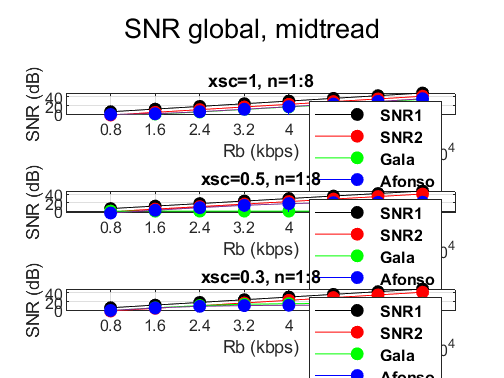



figure(6)

subplot(3,1,1)
plot(Rb,SNR1,'k',Rb,SNR2,'r',Rb,SNRq_valores_tread_1,'g',Rb,SNRq_valores_tread_1_af)
hold on
h1 = stem(Rb, SNR1, 'k', 'Marker','o', 'MarkerFaceColor','k', 'DisplayName','SNR1');
h2 = stem(Rb, SNR2, 'r', 'Marker','o', 'MarkerFaceColor','r', 'DisplayName','SNR2');
h3 = stem(Rb, SNRq_valores_tread_1, 'g', 'Marker','o', 'MarkerFaceColor','g', 'DisplayName','Gala');
h4 = stem(Rb, SNRq_valores_tread_1_af, 'b', 'Marker','o', 'MarkerFaceColor','b', 'DisplayName','Afonso');
hold off
ax = gca;
ax.XTick = Rb;
grid

% Nombre a los ejes y titulo
xlabel('Rb (kbps)'), ylabel('SNR (dB)'), title('xsc=1, n=1:8');
legend([h1, h2, h3, h4], 'fontsize',8,'FontWeight','bold');

subplot(3,1,2)
plot(Rb,SNR1,'k',Rb,SNR2,'r',Rb,SNRq_valores_tread_0_5,'g',Rb,SNRq_valores_tread_0_5_af)
hold on
h1 = stem(Rb, SNR1, 'k', 'Marker','o', 'MarkerFaceColor','k', 'DisplayName','SNR1');
h2 = stem(Rb, SNR2, 'r', 'Marker','o', 'MarkerFaceColor','r', 'DisplayName','SNR2');
h3 = stem(Rb, SNRq_valores_tread_0_5, 'g', 'Marker','o', 'MarkerFaceColor','g', 'DisplayName','Gala');
h4 = stem(Rb, SNRq_valores_tread_0_5_af, 'b', 'Marker','o', 'MarkerFaceColor','b', 'DisplayName','Afonso');
hold off
ax = gca;
ax.XTick = Rb;
grid

%% Nombre a los ejes y titulo
xlabel('Rb (kbps)'), ylabel('SNR (dB)'), title('xsc=0.5, n=1:8');
legend([h1, h2, h3, h4], 'fontsize',8,'FontWeight','bold');

subplot(3,1,3)
plot(Rb,SNR1,'k',Rb,SNR2,'r',Rb,SNRq_valores_tread_0_3,'g',Rb,SNRq_valores_tread_0_3_af)
hold on
h1 = stem(Rb, SNR1, 'k', 'Marker','o', 'MarkerFaceColor','k', 'DisplayName','SNR1');
h2 = stem(Rb, SNR2, 'r', 'Marker','o', 'MarkerFaceColor','r', 'DisplayName','SNR2');
h3 = stem(Rb, SNRq_valores_tread_0_3, 'g', 'Marker','o', 'MarkerFaceColor','g', 'DisplayName','Gala');
h4 = stem(Rb, SNRq_valores_tread_0_3_af, 'b', 'Marker','o', 'MarkerFaceColor','b', 'DisplayName','Afonso');
hold off
ax = gca;
ax.XTick = Rb;
grid

%%Nombre a los ejes y titulo
xlabel('Rb (kbps)'), ylabel('SNR (dB)'), title('xsc=0.3, n=1:8');
legend([h1, h2, h3, h4], 'fontsize',8,'FontWeight','bold');

sgtitle('SNR global, midtread');

- Explicad los resultados obtenidos.

Para una sobreacarga de 0.3 observamos que para valores pequeños de bits (n), la SNR se aproxima a la SNR2 

y a medida que n toma valores mas altos la SNR global tiende a estabilizarse en 16 dB

### Archivo de voz Afonso con xsc=1

n=1:8;
xsc=1;
[x, fs] = audioread('Afonso_8khz.wav');
SNRq_valores_riser = zeros(size(n));

% for i=1:length(n)
% 
%     [y, ~,~, ~, ~] = qmidriser(x,xsc,i);  % Cuantificacion midriser al fichero Afonso
%     SNRr = SNR(x,y); % SNR de la señal cuantificada    
%     SNRq_valores_riser(i) = SNRr;
%     
% end
% Se inicializa el vector de SNR
SNRq_valores_tread = zeros(size(n));

for i=1:length(n)

    [y, ~,~, ~, ~] = qmidtread(x,xsc,i);  % Cuantificacion midrtread al fichero Afonso
    SNRt = SNR(x,y); % SNR de la señal cuantificada    
    SNRq_valores_tread(i) = SNRt;
    
end

    Rb=fs*n;
    SNR1 = 6.02*n;
    SNR2 = 6.02*n - 7.27;
               
% plot(Rb,SNR1,'k',Rb,SNR2,'r',Rb,SNRq_valores_riser,'g',Rb,SNRq_valores_tread,'m'); ax = gca; ax.XTick = Rb; grid 
% 
% % Nombre a los ejes y titulo
% xlabel('Rb (kbps)'),ylabel('SNR (dB)'),title('SNR global, xsc=1,n=1:8');
% 
% % Leyenda 
% legend('SNR1','SNR2','Afonso midriser','Afonso midtread','fontsize',8,'FontWeight','bold');

### Afonso con xsc =0.5

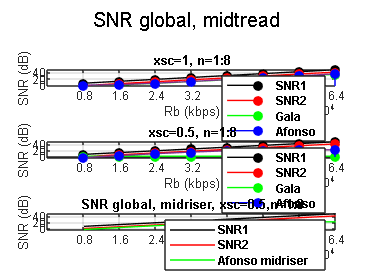

n=1:8;
xsc =0.5;
[x, fs] = audioread('Afonso_8khz.wav');
SNRq_valores_riser = zeros(size(n));

for i=1:length(n)

    [y, ~,~, ~, ~] = qmidriser(x,xsc,i);  % Cuantificacion midriser al fichero Afonso
    SNRr = SNR(x,y); % SNR de la señal cuantificada    
    SNRq_valores_riser(i) = SNRr;
    
end

 Rb=fs*n;
    SNR1 = 6.02*n;
    SNR2 = 6.02*n - 7.27;
               
plot(Rb,SNR1,'k',Rb,SNR2,'r',Rb,SNRq_valores_riser,'g'); ax = gca; ax.XTick = Rb; grid 

% Nombre a los ejes y titulo
xlabel('Rb (kbps)'),ylabel('SNR (dB)'),title('SNR global, midriser, xsc=0.5,n=1:8');

% Leyenda 
legend('SNR1','SNR2','Afonso midriser','fontsize',8,'FontWeight','bold');


% Observamos que al disminuir el valor de sobrecarga del cuantificador
% doblamos la potencia de la señal (+6 dB), pasando por ejemplo, en Rb=8kbps de -12dB de SNR 
% con xsc =1 a una SNR de -6 dB con xsc=0.5

### Afonso con xsc=0.3

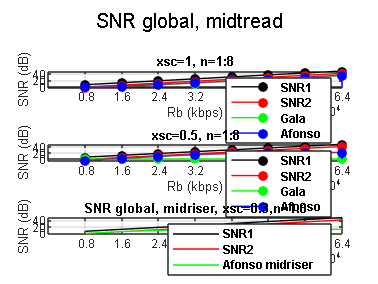

n=1:8;
xsc =0.3;
[x, fs] = audioread('Afonso_8khz.wav');
SNRq_valores_riser = zeros(size(n));

for i=1:length(n)

    [y, ~,~, ~, ~] = qmidriser(x,xsc,i);  % Cuantificacion midriser al fichero Afonso
    SNRr = SNR(x,y); % SNR de la señal cuantificada    
    SNRq_valores_riser(i) = SNRr;
    
end

 Rb=fs*n;
    SNR1 = 6.02*n;
    SNR2 = 6.02*n - 7.27;
               
plot(Rb,SNR1,'k',Rb,SNR2,'r',Rb,SNRq_valores_riser,'g'); ax = gca; ax.XTick = Rb; grid 

% Nombre a los ejes y titulo
xlabel('Rb (kbps)'),ylabel('SNR (dB)'),title('SNR global, midriser, xsc=0.3,n=1:8');

% Leyenda 
legend('SNR1','SNR2','Afonso midriser','fontsize',8,'FontWeight','bold');